## **ECE 569 Lab 3 Tutorial**

If you are new to MATLAB, this tutorial will help you with the basic commands you will need in order to complete this assignment.

clear all; % delete variables in current Workspace
close all; % close all figures (if any are open)
clc;       % clear the Command Window

#### **Vectors and Matrices**

MATLAB supports both row vectors and column vectors. Here are some examples:

row_vector_1 = zeros(1,6)   % 1 row, 6 columns

row_vector_1 =      0     0     0     0     0     0


row_vector_2 = 1:10         % 1,2,3,4,...,9,10

row_vector_2 =      1     2     3     4     5     6     7     8     9    10



column_vector_1 = ones(5,1) % 5 rows, 1 column

column_vector_1 =      1
     1
     1
     1
     1


column_vector_2 = (3:2:13)' % the ' is the transpose operator

column_vector_2 =      3
     5
     7
     9
    11
    13


Note that you can suppress output by using the semicolon ; at the end of the line.

x_data = rand(3,1); % remove the ; to see the output

To access an element inside a vector, use `()` for indexing. Note that in MATLAB, indexing starts at 1.

row_vector_1(2) = 17            % index 2

row_vector_1 =      0    17     0     0     0     0


row_vector_1(end) = 100         % end gives final index

row_vector_1 =      0    17     0     0     0   100


column_vector_1(end-1) = 2*3    % end-1 works too!

column_vector_1 =      1
     1
     1
     6
     1


You can also define vectors using brackets [ ]

small_primes = [2 3 5 7 11 13]  % row vector

small_primes =      2     3     5     7    11    13


gas_prices = [3.81; 3.99; 4.25] % column vector

gas_prices =     3.8100
    3.9900
    4.2500


Matrices are similarly defined and accessed.

R = ones(3,3)

R =      1     1     1
     1     1     1
     1     1     1


I = eye(3)

I =      1     0     0
     0     1     0
     0     0     1


M = [1 2 3; 4 5 6; 7 8 9]

M =      1     2     3
     4     5     6
     7     8     9



% Change the (2,3) element of R
R(2,3) = 200

R =      1     1     1
     1     1   200
     1     1     1



% Get the 3rd column of R.
% Think: Every row, 3rd column
R(:,3)

ans =      1
   200
     1



% Get the first row of M
% Think: first row, every column
M(1,:)

ans =      1     2     3



% Modify a section of a matrix
M(2:3,1:2) = -1*[11 12; 13 14]

M =      1     2     3
   -11   -12     6
   -13   -14     9



% Transpose a matrix
M'

ans =      1   -11   -13
     2   -12   -14
     3     6     9


You can construct a matrix from column vectors (and also row vectors).

c1 = [10; 20; 30];
c2 = [40; 50; 60];
C = [c1 c2]

C =     10    40
    20    50
    30    60


To check the size of a matrix of vector, use `size()`

size(C)

ans =      3     2


size(C,1) % number of rows

ans = 3

size(C,2) % number of columns

ans = 2

What about a list of matrices? Sometimes, we want to use a single variable to represent a bunch of different matrices of the same size. In this example, we have 5 matrices, $A_1 \dots A_5$ each of which is a 2x2 matrix.

A = zeros(2,2,5);
A(:,:,1) = ones(2,2);
A(:,:,2) = rand(2,2);
A(:,:,3) = [1 2; 3 4];
A(:,:,4) = A(:,:,1) + A(:,:,3);
A

A = A(:,:,1) =

     1     1
     1     1


A(:,:,2) =

    0.1576    0.9572
    0.9706    0.4854


A(:,:,3) =

     1     2
     3     4


A(:,:,4) =

     2     3
     4     5


A(:,:,5) =

     0     0
     0     0


Matrix multiplication, scalar multiplication, addition, subtraction work as you would expect, but MATLAB also allows for element-wise operators.

x = 1:4;
5*x

ans =      5    10    15    20


2+x

ans =      3     4     5     6


x.^2 % square each element

ans =      1     4     9    16


exp(x) % e^x1 e^x2 ...

ans =     2.7183    7.3891   20.0855   54.5982


sin(x) % sin(x1) sin(x2) ...

ans =     0.8415    0.9093    0.1411   -0.7568



A = magic(3);
B = diag([1 2 3])

B =      1     0     0
     0     2     0
     0     0     3


A*B    % matrix multiplication

ans =      8     2    18
     3    10    21
     4    18     6


A.*B   % element-wise multiplcation

ans =      8     0     0
     0    10     0
     0     0     6


Be careful with functions with matrices. Sometimes they are applied elementwise and sometimes they are applied to the entire matrix. If you don't know, use the `help` command in the Command Window

exp(A)   % element-wise exponential

ans = 1.0e+03 *

    2.9810    0.0027    0.4034
    0.0201    0.1484    1.0966
    0.0546    8.1031    0.0074


expm(A)  % matrix exponential

ans = 1.0e+06 *

    1.0898    1.0896    1.0897
    1.0896    1.0897    1.0897
    1.0896    1.0897    1.0897


help expm

 expm  Matrix exponential.
    expm(A) is the matrix exponential of A and is computed using
    a scaling and squaring algorithm with a Pade approximation.
 
    Although it is not computed this way, if A has a full set
    of eigenvectors V with corresponding eigenvalues D then
    [V,D] = EIG(A) and expm(A) = V*diag(exp(diag(D)))/V.
 
    EXP(A) computes the exponential of A element-by-element.
 
    See also expmv, logm, sqrtm, funm.

    Documentation for expm
    Other uses of expm



**Plotting and Subplots**

We can plot two vectors (x vector, y vector) using the plot command. In this example, we simulate a spring-mass system with damping using a state space model (simulating a model is not required on this homework!)

% model coefficients
k = 3;
b = 1;
m = 2;

% state space model
A = [0 1; -k/m -b/m];
B = [0; 0];
C = eye(2);
D = 0;
sys = ss(A,B,C,D);

% time vector
t = (0:0.1:20)'; 

% initial condition
x0 = [1; 0];

% simulation (input u = 0*t)
[y,t] = lsim(sys,0*t,t,x0);
q = y(:,1); % position
v = y(:,2); % velocity

Now we have two vectors q and v which we would like to plot as functions of time. We need to use `subplot` to select which part of the figure to graph. We first tell subplot that we want the figures arranged in a (2,1) column vector, and then specify the index. If you wanted to plot 4 signals, then you would have the command `subplot(4,1,1) `and then `subplot(4,1,2), `etc. Sometimes you want to plot a row vector. That is not a problem either for the plot function.

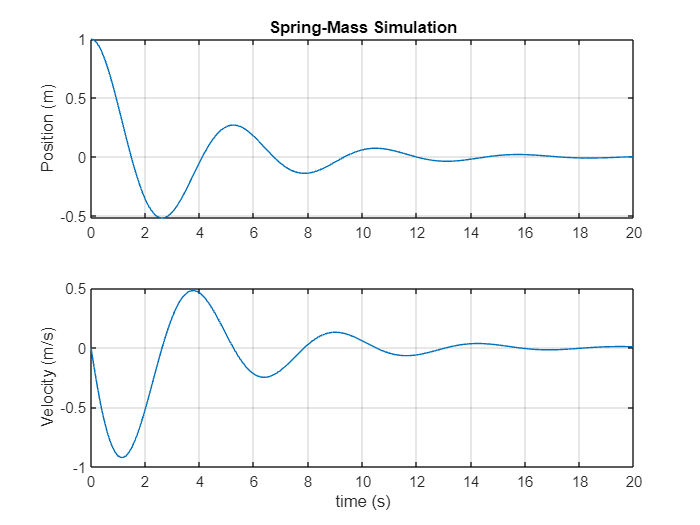

% plotting
figure()
subplot(2,1,1); plot(t,q); grid on; ylabel('Position (m)');
title('Spring-Mass Simulation')
subplot(2,1,2); plot(t,v); grid on; ylabel('Velocity (m/s)');
xlabel('time (s)');

**Loops**

Best seen with an example or two.

N = 10;
A = zeros(3,3,N);

for i=1:N
    A(:,:,i) = i * ones(3,3);
end
A

A = A(:,:,1) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,2) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,3) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,4) =

     4     4     4
     4     4     4
     4     4     4


A(:,:,5) =

     5     5     5
     5     5     5
     5     5     5


A(:,:,6) =

     6     6     6
     6     6     6
     6     6     6


A(:,:,7) =

     7     7     7
     7     7     7
     7     7     7


A(:,:,8) =

     8     8     8
     8     8     8
     8     8     8


A(:,:,9) =

     9     9     9
     9     9     9
     9     9     9


A(:,:,10) =

    10    10    10
    10    10    10
    10    10    10



% compute row sums of A_i
A_first_row_sums = zeros(N,1);
for i=1:N
    Ai = A(:,:,i);  % get the ith matrix
    A_first_row_sums(i) = sum(Ai(1,:));
end
A_first_row_sums'

ans =      3     6     9    12    15    18    21    24    27    30


**If ElseIf Else**

N = 10;
A = zeros(3,3,N);

for i=1:N
    if mod(i,3) == 0
        % i = 3,6,9,...
        A(:,:,i) = 3*ones(3,3);
    elseif mod(i,3) == 1
        % i = 1,4,7,...
        A(:,:,i) = ones(3,3);
    else
        A(:,:,i) = 2*ones(3,3);
    end
end
A

A = A(:,:,1) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,2) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,3) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,4) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,5) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,6) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,7) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,8) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,9) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,10) =

     1     1     1
     1     1     1
     1     1     1


**Inline Functions**

You can create your own one-line functions. The syntax is a little strange, but not difficult with practice.

my_sum = @(x,y) x+y;
z = my_sum(3,4)

z = 7


my_matrix = @(x) [0 x 0; 0 0 x; x 0 0];
A = my_matrix(7)

A =      0     7     0
     0     0     7
     7     0     0


**Functions**

For functions that take multiple lines, you can either put them into their own .m file (with the same name as the function itself) or put them at the bottom of your live script.

[s,d] = Add_Sub(5,7)

s = 12

d = -2

s1 = My_Square(12)

s1 = 144

s2 = My_Square(-3) % ALWAYS test your functions!

s2 = 0

function [the_sum, the_diff] = Add_Sub(x,y)
    the_sum = x+y;
    the_diff = x-y;
end

function y = My_Square(n)
total = 0;
for i=1:n
    total = total + n;
end
y = total;
end